## let's first download our dataset.

if ~exist(".\Downloads",'dir')
    mkdir(".\Downloads");
end
% 
% dates = datetime("01-Jan-2024","Format","yyyyMMdd"):calmonths(1):datetime("01-Jul-2024");
dates = datetime("01-Feb-2005","Format","yyyyMMdd"):calmonths(1):datetime("01-Jan-2006");
dates = string(dates);

for index=1:length(dates)
    url="http://mis.nyiso.com/public/csv/pal/"+dates(index)+"pal_csv.zip";
    filename=fullfile(downloadFolder,dates(index));
    websave(filename,url);
    beep;
    %http://mis.nyiso.com/public/csv/pal/20240701pal_csv.zip
end

## Unzip the downloaded files to dataset folder

if ~exist(datasetFolder,"dir")
    mkdir(datasetFolder);
end

for index=1:length(dates)
    filename=fullfile(downloadFolder,dates(index));
    unzip(filename,datasetFolder);
end
beep

## Constants

downloadFolder = fullfile(".\Downloads")

downloadFolder = ".\Downloads"

datasetFolder = ".\Dataset"

datasetFolder = ".\Dataset"

prj = currentProject();

files = dir(".\Dataset\*.csv");

dbtype(fullfile(files(1).folder,files(1).name),'1:5');

1     "Time Stamp","Time Zone","Name","PTID","Load"
2     "02/01/2005 00:00:00","EST","CAPITL",61757,1250.4
3     "02/01/2005 00:00:00","EST","CENTRL",61754,1942.1
4     "02/01/2005 00:00:00","EST","DUNWOD",61760,612.2
5     "02/01/2005 00:00:00","EST","GENESE",61753,1131.6


## Read the entire data in Dataset folder

ds = datastore(datasetFolder,TextscanFormats={'%{MM/dd/yyyy HH:mm:ss}D','%C','%C','%d','%f'});

## Select the required Attributes

ds.SelectedVariableNames = {'TimeStamp', 'Name','Load'};
ds.preview

ans = 8×3 table
         TimeStamp          Name      Load 
    ___________________    ______    ______

    02/01/2005 00:00:00    CAPITL    1250.4
    02/01/2005 00:00:00    CENTRL    1942.1
    02/01/2005 00:00:00    DUNWOD     612.2
    02/01/2005 00:00:00    GENESE    1131.6
    02/01/2005 00:00:00    HUD VL    1154.9
    02/01/2005 00:00:00    LONGIL    2270.5
    02/01/2005 00:00:00    MHK VL     901.3
    02/01/2005 00:00:00    MILLWD     272.3


raw = ds.readall;
unstacked = unstack(raw,"Load","Name");

unstacked.Properties.VariableNames(1)="Date";

head(unstacked)

           Date            CAPITL    CENTRL    DUNWOD    GENESE    HUDVL     LONGIL    MHKVL    MILLWD    N_Y_C_    NORTH     WEST 
    ___________________    ______    ______    ______    ______    ______    ______    _____    ______    ______    _____    ______

    02/01/2005 00:00:00    1250.4    1942.1    612.2     1131.6    1154.9    2270.5    901.3    272.3     5271.6    811.7    1887.8
    02/01/2005 00:05:00         0         0        0          0         0         0        0        0          0        0         0
    02/01/2005 00:10:00    1232.5    1978.1    581.1     1119.5

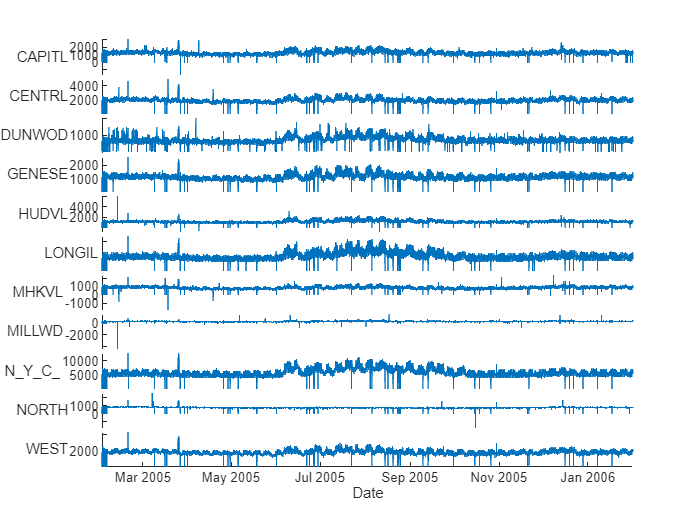

stackedplot(unstacked,XVariable="Date");

## Convert unstacked to timetable for more time related functionalities.

tt = table2timetable(unstacked);
isregular(tt)

ans = logical
   0


## Select Region to Clean it's Signal

region="DUNWOD";
regionSignal = tt(:,region);
regionSignal.Properties.VariableNames="Load";
regionSignal

regionSignal = 106163×1 timetable
           Date            Load 
    ___________________    _____

    02/01/2005 00:00:00    612.2
    02/01/2005 00:05:00        0
    02/01/2005 00:10:00    581.1
    02/01/2005 00:15:00    569.5
    02/01/2005 00:20:00    599.3
    02/01/2005 00:25:00    581.1
    02/01/2005 00:30:00      586
    02/01/2005 00:35:00    584.8
    02/01/2005 00:40:00    527.8
    02/01/2005 00:41:20    538.4
    02/01/2005 00:42:50      542
    02/01/2005 00:50:00    510.8
    02/01/2005 00:55:00    556.7
    02/01/2005 01:00:00    514.1
    02/01/2005 01:05:00        0
    02/01/2005 01:10:00    511.4


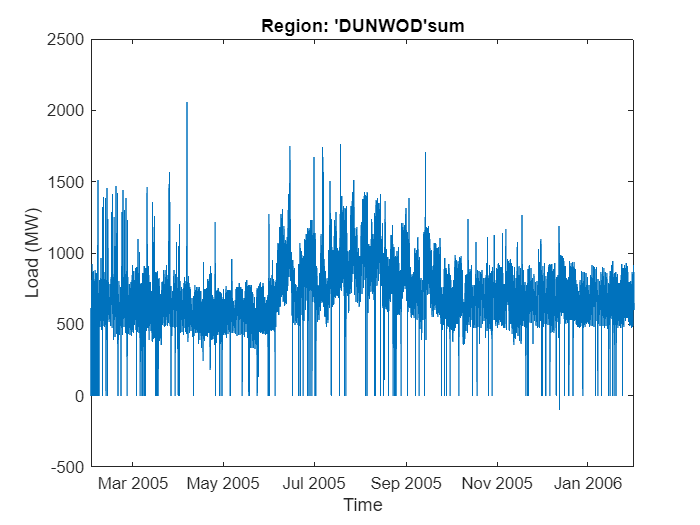

plot(regionSignal,"Date","Load")
xlabel("Time")
ylabel("Load (MW)")
title("Region: '"+region+"'sum")

## Let's remove all the zeroes, if any, and replace with estimates.

First let's put zero in place of all missing values.

if sum(ismissing(regionSignal))
    missingZeroSignal = standardizeMissing(regionSignal,0)

missingZeroSignal = 106163×1 timetable
           Date            Load 
    ___________________    _____

    02/01/2005 00:00:00    612.2
    02/01/2005 00:05:00      NaN
    02/01/2005 00:10:00    581.1
    02/01/2005 00:15:00    569.5
    02/01/2005 00:20:00    599.3
    02/01/2005 00:25:00    581.1
    02/01/2005 00:30:00      586
    02/01/2005 00:35:00    584.8
    02/01/2005 00:40:00    527.8
    02/01/2005 00:41:20    538.4
    02/01/2005 00:42:50      542
    02/01/2005 00:50:00    510.8
    02/01/2005 00:55:00    556.7
    02/01/2005 01:00:00    514.1
    02/01/2005 01:05:00      NaN
    02/01/2005 01:10:00    511.4


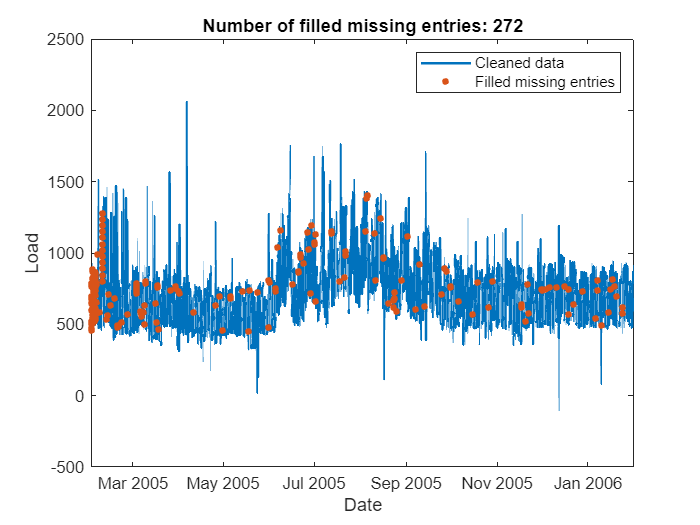

% Fill missing data
[cleanSignal,missingIndices] = fillmissing(missingZeroSignal,"linear");

% Display results
figure

% Plot cleaned data
plot(missingZeroSignal.Date,cleanSignal.Load,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(missingZeroSignal.Date(missingIndices),cleanSignal.Load(missingIndices),".", ...
    "MarkerSize",12,"SeriesIndex",2,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices))

hold off
legend
ylabel("Load")
xlabel("Date")
clear missingIndices
else
    cleanSignal=regionSignal
end

## Let's clean the outliers now

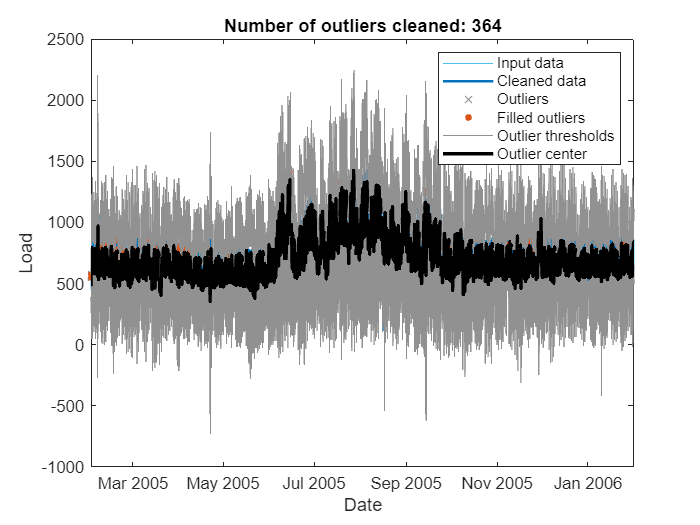

% Fill outliers
[cleanSignal,outlierIndices,thresholdLow,thresholdHigh,center] =  ...
    filloutliers(cleanSignal,"linear","movmedian",hours(11));

% Display results
figure
plot(cleanSignal.Date,cleanSignal.Load,"SeriesIndex",6, ...
    "DisplayName","Input data")
hold on
plot(cleanSignal.Date,cleanSignal.Load,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")

% Plot outliers
plot(cleanSignal.Date(outlierIndices),cleanSignal.Load(outlierIndices),"x", ...
    "Color",[145 145 145]/255,"DisplayName","Outliers")

% Plot filled outliers
plot(cleanSignal.Date(outlierIndices),cleanSignal.Load(outlierIndices),".", ...
    "MarkerSize",12,"SeriesIndex",2,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([cleanSignal.Date(:); missing; cleanSignal.Date(:)], ...
    [thresholdHigh.Load(:); missing; thresholdLow.Load(:)], ...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

% Plot outlier center
plot(cleanSignal.Date,center.Load,"SeriesIndex","none","LineWidth",2, ...
    "DisplayName","Outlier center")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
ylabel("Load")
xlabel("Date")

clear thresholdLow thresholdHigh center

## Let's smooth the data now.

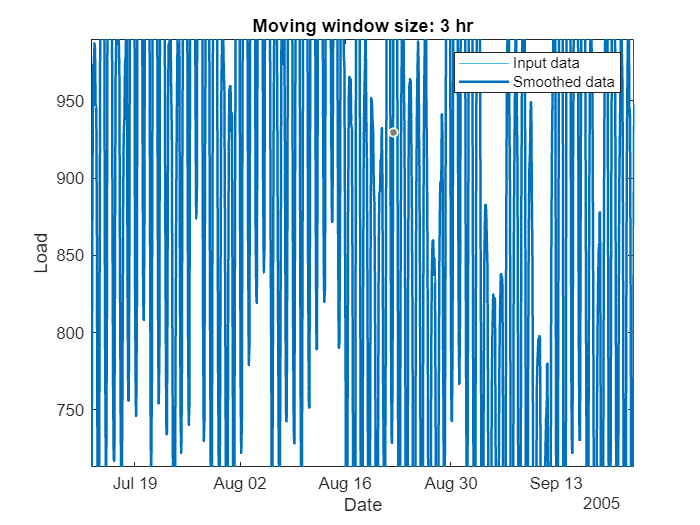

% Smooth input data
[cleanSignal,winSize2] = smoothdata(cleanSignal,"movmedian",hours(3));

% Display results
figure
plot(cleanSignal.Date,cleanSignal.Load,"SeriesIndex",6, ...
    "DisplayName","Input data")
hold on
plot(cleanSignal.Date,cleanSignal.Load,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize2));
legend
ylabel("Load")
xlabel("Date")

clear winSize2

cleanSignal

cleanSignal = 59009×1 timetable
           Date             Load 
    ___________________    ______

    01/01/2024 00:00:00    543.64
    01/01/2024 00:05:00    543.57
    01/01/2024 00:10:00    542.53
    01/01/2024 00:15:00    541.49
    01/01/2024 00:20:00    541.07
    01/01/2024 00:25:00    540.65
    01/01/2024 00:30:00    540.42
    01/01/2024 00:35:00     540.2
    01/01/2024 00:40:00    539.46
    01/01/2024 00:45:00    538.73
    01/01/2024 00:50:00    538.43
    01/01/2024 00:55:00    538.13
    01/01/2024 01:00:00    537.05
    01/01/2024 01:05:00    532.67
    01/01/2024 01:10:00    522.24
    01/01/2024 01:15:00    516.51


## Now let's regularize the time stamps.

summary(table(diff(cleanSignal.Date)))

Variables:

    Var1: 106162×1 duration

        Values:

            Min       00:00:01
            Median    00:05:00
            Max       01:05:00



Timestamps are not even.

cleanSignal=retime(cleanSignal,cleanSignal.Date(1):minutes(5):cleanSignal.Date(end),'linear')

cleanSignal = 105120×1 timetable
           Date             Load 
    ___________________    ______

    02/01/2005 00:00:00       542
    02/01/2005 00:05:00       542
    02/01/2005 00:10:00       542
    02/01/2005 00:15:00       542
    02/01/2005 00:20:00       542
    02/01/2005 00:25:00     541.8
    02/01/2005 00:30:00     541.6
    02/01/2005 00:35:00     541.6
    02/01/2005 00:40:00     541.6
    02/01/2005 00:45:00    541.54
    02/01/2005 00:50:00     541.4
    02/01/2005 00:55:00     539.7
    02/01/2005 01:00:00     538.2
    02/01/2005 01:05:00     538.2
    02/01/2005 01:10:00    535.55
    02/01/2005 01:15:00     532.9


summary(table(diff(cleanSignal.Date)))

Variables:

    Var1: 105119×1 duration

        Values:

            Min       00:05:00
            Median    00:05:00
            Max       00:05:00



## Let's integrate whether data.

d = dir(fullfile(downloadFolder, "Weather", "HistWeather/*hourly.txt"));
disp(compose("Total data on disk to search through: %.2f GB", sum([d.bytes])/(2^30)))

Total data on disk to search through: 2.11 GB


dbtype(fullfile(d(1).folder,d(1).name),"1:5")

1     WBAN,Date,Time,StationType,SkyCondition,SkyConditionFlag,Visibility,VisibilityFlag,WeatherType,WeatherTypeFlag,DryBulbFarenheit,DryBulbFarenheitFlag,DryBulbCelsius,DryBulbCelsiusFlag,WetBulbFarenheit,WetBulbFarenheitFlag,WetBulbCelsius,WetBulbCelsiusFlag,DewPointFarenheit,DewPointFarenheitFlag,DewPointCelsius,DewPointCelsiusFlag,RelativeHumidity,RelativeHumidityFlag,WindSpeed,WindSpeedFlag,WindDirection,WindDirectionFlag,ValueForWindCharacter,ValueForWindCharacterFlag,StationPressure,StationPressureFlag,PressureTendency,PressureTendencyFlag,PressureChange,PressureChangeFlag,SeaLevelPressure,SeaLevelPressureFlag,RecordType,RecordTypeFlag,HourlyPrecip,HourlyPrecipFlag,Altimeter,AltimeterFlag
2     03011,20070501,0050,0,CLR, ,10.00, , , ,45, ,7.0, ,38, ,3.3, ,30, ,-1.0, , 56, , 5, ,140, , , ,21.57, , , , , ,M, ,AA, , , ,30.25, 
3     03011,20070501,0150,0,CLR, ,10.00, , , ,45, ,7.0, ,38, ,3.3, ,30, ,-1.0, , 56, , 0, ,000, , , ,21.56, , , , , ,M, ,AA, , , ,30.24, 
4     03011,2007050

## Let's read the entire data using datastore

dsW = datastore(fullfile(datasetFolder,"HistWeather","*hourly.txt"),...
    'SelectedVariableNames',{'WBAN','Date','Time','DryBulbFarenheit','DewPointFarenheit'},...
    'ReadSize',1e6,...
    'TreatAsMissing',{'M'},...
    'SelectedFormats',{'%f','%s','%s','%f','%f'},...
    'TextType','String')

dsW =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\MATLAB\Projects\LorenShureEDA\Dataset\HistWeather\200705hourly.txt';
                             ' ...\MATLAB\Projects\LorenShureEDA\Dataset\HistWeather\200706hourly.txt';
                             ' ...\MATLAB\Projects\LorenShureEDA\Dataset\HistWeather\200707hourly.txt'
                              ... and 5 more
                             }
                    Folders: {
                             'C:\Users\karti\MATLAB\Projects\LorenShureEDA\Dataset\HistWeather'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
         VariableNamingRule: 'modify'
          ReadVariableNames: true
              VariableNames: {'WBAN', 'Date', 'Time' ... and 41 more}
             DatetimeLocale: en_US

  Text Format Properties:
    

preview(dsW)

ans = 8×5 table
    WBAN       Date        Time     DryBulbFarenheit    DewPointFarenheit
    ____    __________    ______    ________________    _________________

    3011    "20070501"    "0050"           45                  30        
    3011    "20070501"    "0150"           45                  30        
    3011    "20070501"    "0250"           45                  30        
    3011    "20070501"    "0350"           43                  30        
    3011    "20070501"    "0450"           43                  30        
    3011    "20070501"    "0550"           43                  30        
    3011    "20070501"    "0650"           46                  30        
    3011    "20070501"    "0750"           54                  28        


We only need stations in New york so:

stationList = [14735, 94790, 04725, 14733, 14748, 94745, 04781, 94789, 14732, ...
    94761, 54746, 64776, 14757, 14768, 14714, 14771, 64775]';

## Let's use tall array to only get the data that the ram can manage. And swap from disk as required.

rawDsW = tall(dsW)

rawDsW =

  M×5 tall table

    WBAN       Date        Time     DryBulbFarenheit    DewPointFarenheit
    ____    __________    ______    ________________    _________________

    3011    "20070501"    "0050"           45                  30        
    3011    "20070501"    "0150"           45                  30        
    3011    "20070501"    "0250"           45                  30        
    3011    "20070501"    "0350"           43                  30        
    3011    "20070501"    "0450"           43                  30        
    3011    "20070501"    "0550"           43                  30        
    3011    "20070501"    "0650"           46                  30        
    30

idxwban = ismember(rawDsW.WBAN,stationList)

idxwban =

  M×1 tall logical array

   0
   0
   0
   0
   0
   0
   0
   0
   :
   :



weatherDataRaw = rawDsW(idxwban,:)

weatherDataRaw =

  M×5 tall table

    WBAN       Date        Time     DryBulbFarenheit    DewPointFarenheit
    ____    __________    ______    ________________    _________________

    4725    "20070501"    "0053"           46                  26        
    4725    "20070501"    "0153"           44                  26        
    4725    "20070501"    "0253"           43                  27        
    4725    "20070501"    "0353"           42                  27        
    4725    "20070501"    "0453"           41                  27        
    4725    "20070501"    "0553"           42                  28        
    4725    "20070501"    "0653"           44                  30       

## Let's join date and time and convert it in New york timezone to handle the time changes.

weatherDataRaw.Date = join([weatherDataRaw.Date,weatherDataRaw.Time],'')

weatherDataRaw =

  M×5 tall table

    WBAN         Date          Time     DryBulbFarenheit    DewPointFarenheit
    ____    ______________    ______    ________________    _________________

    4725    "200705010053"    "0053"           46                  26        
    4725    "200705010153"    "0153"           44                  26        
    4725    "200705010253"    "0253"           43                  27        
    4725    "200705010353"    "0353"           42                  27        
    4725    "200705010453"    "0453"           41                  27        
    4725    "200705010553"    "0553"           42                  28        
    4725    "200705010653"    "0653"    

weatherDataRaw.Date = datetime(weatherDataRaw.Date,'InputFormat','yyyyMMddHHmm', ...
    'TimeZone','America/New_York')

weatherDataRaw =

  M×5 tall table

    WBAN            Date             Time     DryBulbFarenheit    DewPointFarenheit
    ____    ____________________    ______    ________________    _________________

    4725    01-May-2007 00:53:00    "0053"           46                  26        
    4725    01-May-2007 01:53:00    "0153"           44                  26        
    4725    01-May-2007 02:53:00    "0253"           43                  27        
    4725    01-May-2007 03:53:00    "0353"           42                  27        
    4725    01-May-2007 04:53:00    "0453"           41                  27        
    4725    01-May-2007 05:53:00    "0553"           42                  28 

weatherDataRaw.Temperature=[weatherDataRaw.DryBulbFarenheit, weatherDataRaw.DewPointFarenheit];

weatherDataRaw(:,{'Time','DryBulbFarenheit','DewPointFarenheit'})=[]

Unrecognized table variable name 'Time'.

weatherData = gather(weatherDataRaw)

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 2 min 18 sec
Evaluation completed in 2 min 18 sec


weatherData = 122147×3 table
    WBAN            Date            Temperature
    ____    ____________________    ___________

    4725    01-May-2007 00:53:00     46    26  
    4725    01-May-2007 01:53:00     44    26  
    4725    01-May-2007 02:53:00     43    27  
    4725    01-May-2007 03:53:00     42    27  
    4725    01-May-2007 04:53:00     41    27  
    4725    01-May-2007 05:53:00     42    28  
    4725    01-May-2007 06:53:00     44    30  
    4725    01-May-2007 07:53:00     46    33  
    4725    01-May-2007 08:53:00     50    32  
    4725    01-May-2007 09:53:00     51    31  
    4725    01-May-2007 10:53:00     52    28  
    4725    01-May-2007 11:53:00     53    29  
    4725    01-May-2007 12:53:00     54    31  
    4725    01-May-2007 13:53:00     55    29  
    4725    01-May-2007 14:53:00     56    32  
    4725    01-May-2007 15:53:00     54    34  


weatherData = unstack(weatherData, 'Temperature','WBAN')

weatherData = 55017×18 table
            Date             x4725        x4781         x14714        x14732        x14733        x14735       x14748      x14757       x14768        x14771        x54746        x64775        x64776        x94745        x94761        x94789        x94790  
    ____________________    ________    __________    __________    __________    __________    __________    ________    ________    __________    __________    __________    __________ 

weatherData = sortrows(weatherData, 'Date')

weatherData = 55017×18 table
            Date              x4725         x4781         x14714        x14732        x14733        x14735        x14748        x14757        x14768        x14771        x54746        x64775        x64776        x94745        x94761        x94789        x94790  
    ____________________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ________

weatherTT = table2timetable(weatherData)

weatherTT = 55017×17 timetable
            Date              x4725         x4781         x14714        x14732        x14733        x14735        x14748        x14757        x14768        x14771        x54746        x64775        x64776        x94745        x94761        x94789        x94790  
    ____________________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ______

weatherTT = retime(weatherTT,'hourly','mean')

weatherTT = 5881×17 timetable
            Date             x4725       x4781        x14714       x14732      x14733      x14735      x14748      x14757      x14768      x14771       x54746        x64775        x64776       x94745      x94761      x94789      x94790 
    ____________________    ________    ________    __________    ________    ________    ________    ________    ________    ________    ________    __________    __________    __________ 

dataSparsityPlot(weatherTT)

Unrecognized function or variable 'dataSparsityPlot'.